syms omega;
z3 = (1 / (1 + (1j * omega)))

$$z3 = \frac{1}{1+1\,\omega \,\mathrm{i}}$$

z4 = ((1j * omega) / (1 + (1j * omega)))

$$z4 = \frac{1\,\omega \,\mathrm{i}}{1+1\,\omega \,\mathrm{i}}$$


r3 = matlabFunction(abs(z3))

r3 = function_handle with value:
    @(omega)1.0./abs(omega.*1i+1.0)


t3 = matlabFunction(angle(z3))

t3 = function_handle with value:
    @(omega)angle(1.0./(omega.*1i+1.0))



r4 = matlabFunction(abs(z4))

r4 = function_handle with value:
    @(omega)abs(omega)./abs(omega.*1i+1.0)


t4 = matlabFunction(angle(z4))

t4 = function_handle with value:
    @(omega)angle((omega.*1i)./(omega.*1i+1.0))


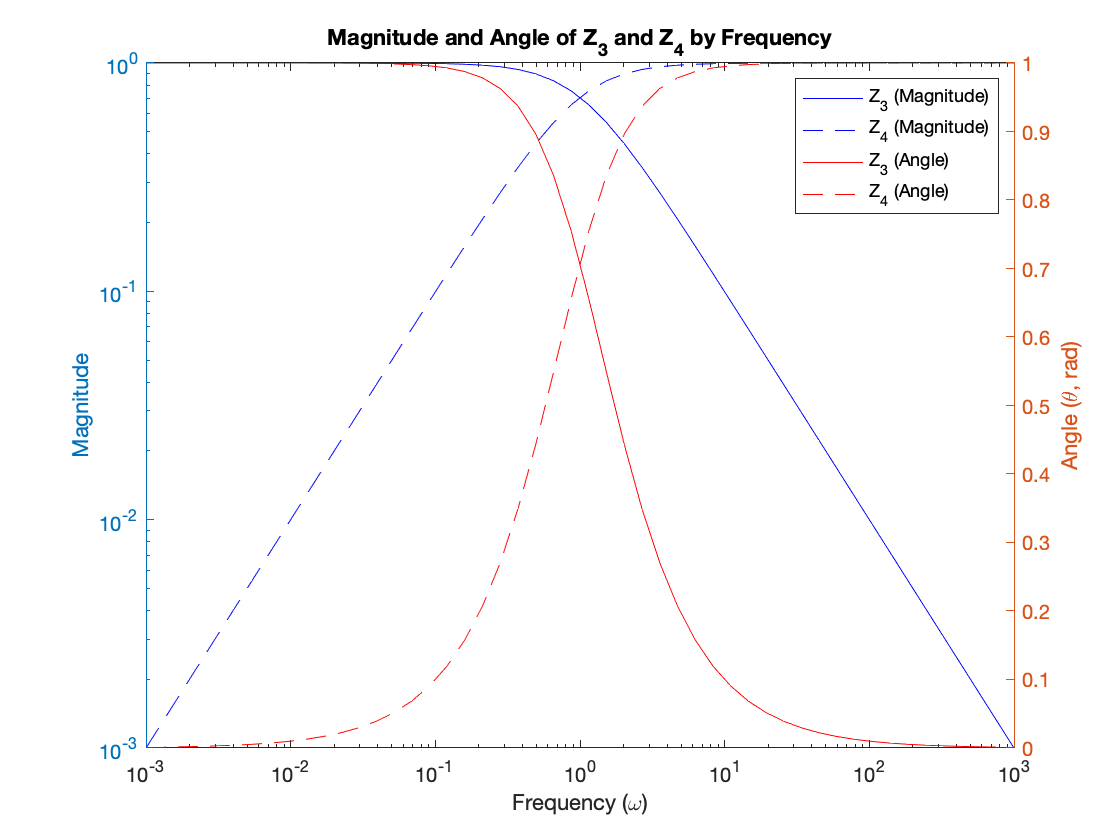


omegas = logspace(-3, 3);

figure(1); clf;
yyaxis left;
loglog(omegas, r3(omegas), 'b-'); hold on;
loglog(omegas, r4(omegas), 'b--');
ylabel("Magnitude");

yyaxis right;
semilogx(omegas, r3(omegas), 'r-');
semilogx(omegas, r4(omegas), 'r--'); hold off;
ylabel("Angle (\theta, rad)")

title("Magnitude and Angle of Z_3 and Z_4 by Frequency");
xlabel("Frequency (\omega)");
legend("Z_3 (Magnitude)", "Z_4 (Magnitude)", "Z_3 (Angle)", "Z_4 (Angle)");